clc;clear;close all;
addpath('./flann/');
addpath('./keypointExtraction/');
% addpath('./estimateRigidTransform');
s=100;
gridStep=0.5;
overlap=0.2;
icpSteps=100;
TrMin=0.2;
TrMax=0.8;
%尺度平衡子（让待配准的两幅图比例保持又不过多影响gridstep）
zoomVar=2;
downStep=0.08;

## 转灰度

map1=rgb2gray(imread('Fr1_3.png','png'));
map2=rgb2gray(imread('Fr1_3.png','png'));
map2 = imresize(map2,1.7);
% imshowpair(map1,map2);
tic;




选取harris-Laplace特殊点

 cornersM1=kp_harrislaplace(map1);
 cornersM2=kp_harrislaplace(map2);
 draw(map1,cornersM1,'m1');
 draw(map2,cornersM2,'m2');
 %%%here

选取harris特殊点 

%  cornersM1=detectHarrisFeatures(map1);
%  cornersM2=detectHarrisFeatures(map2);

## 寻找surf和高斯差分极值

% cornersM1 = detectSURFFeatures(map1);
% cornersM2 = detectSURFFeatures(map2);

BRISK

% cornersM1 = detectBRISKFeatures(map1);
% cornersM2 = detectBRISKFeatures(map2);

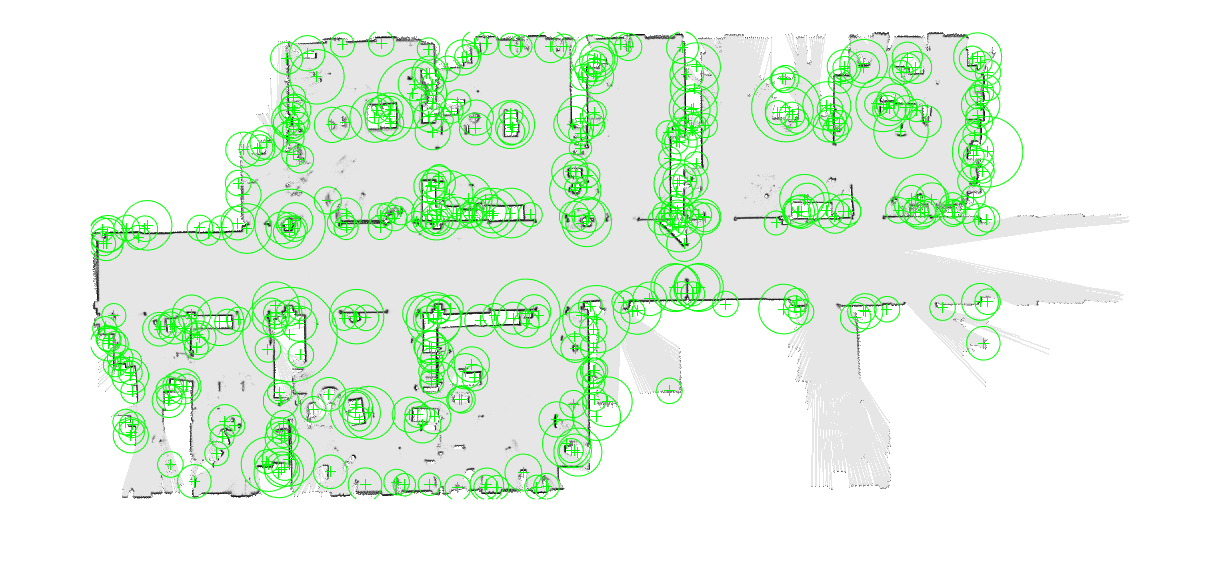

% 1.选取harris角点最强点200个 
% 2.均匀分布选取harris角点最强点200个    (current) 
imshow(map1);hold on;
%plot(selectUniform(cornersM1,200,size(map1)));%
seleCorM1=selectUniform(cornersM1,400,size(map1));% seleCorM1=cornersM1.selectStrongest(300);
plot(seleCorM1);


figure;
imshow(map2);hold on;

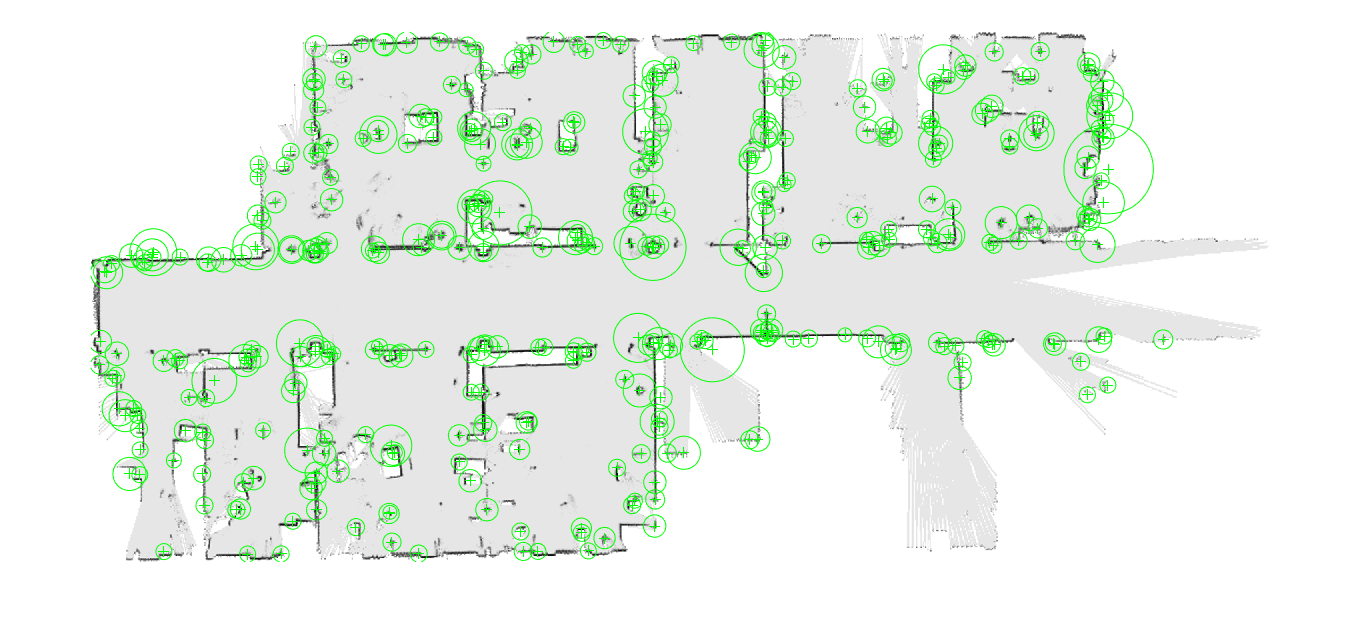

seleCorM2=selectUniform(cornersM2,400,size(map2));
plot(seleCorM2);


zSeleCorM1=SURFPoints(seleCorM1.Location/s,'Scale',seleCorM1.Scale);
zSeleCorM2=SURFPoints(seleCorM2.Location/s,'Scale',seleCorM2.Scale);

## 提取二维点云

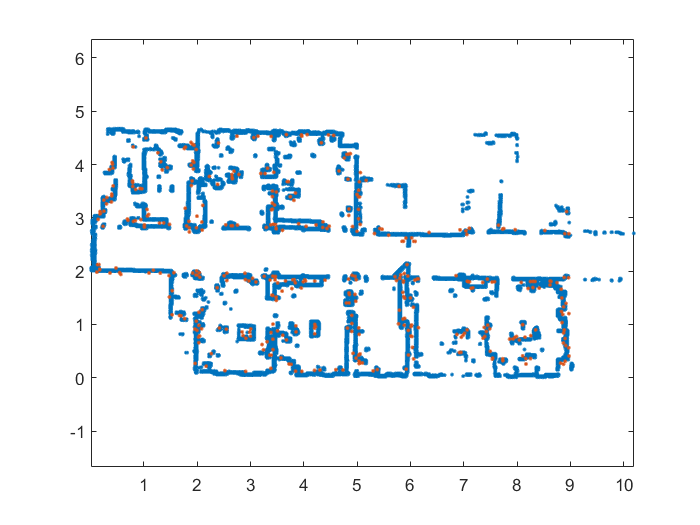

[pcMap3d1,pointCMap1]=exarctPCfroImg(map1);
[pcMap3d2,pointCMap2]=exarctPCfroImg(map2);
pointCMap1=pointCMap1/s;
pointCMap2=pointCMap2/s;
% pcMap3d1=pointCloud ( pcMap3d1.Location/s);
% pcMap3d2=pointCloud ( pcMap3d2.Location/s);
figure;
plot(pointCMap1(:,1),pointCMap1(:,2),'.');hold on;
plot(zSeleCorM1.Location(:,1),zSeleCorM1.Location(:,2),'.');
axis equal

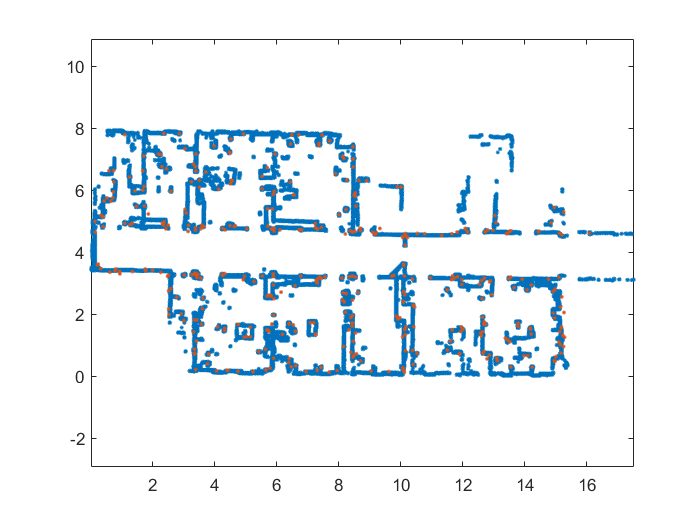

figure;
plot(pointCMap2(:,1),pointCMap2(:,2),'.');hold on;
plot(zSeleCorM2.Location(:,1),zSeleCorM2.Location(:,2),'.');
axis equal

## 基于尺度获取描述子

[M1Desp,M1Scale,M1Seed,M1Norm]=exarctEIG2d(pointCMap1,gridStep,zSeleCorM1,zoomVar); 
[M2Desp,M2Scale,M2Seed,M2Norm]=exarctEIG2d(pointCMap2,gridStep,zSeleCorM2,zoomVar); 

## 匹配

Motion=eigMatch2D(M1Desp,M2Desp,M1Scale,M2Scale,M1Seed,M2Seed,M1Norm,M2Norm,overlap,gridStep,map1,map2,s);

## testcode

close all; plot(s*pointCMap1(:,1),s*pointCMap1(:,2),'.'); hold on plot(s*M1Seed(1,:)',s*M1Seed(2,:)','.','MarkerSize',10 ,'color','red');

## 修正尺度 

s=SQRT((S*COS(THETA))^2+(S*SIN(THETA))^2)

%%根据相似变换和比例公式推倒缩放因子
scaleC=sqrt(sum(Motion(1:2,1).^2));
pointCMap1Scaled = pointCMap1*scaleC;
pointCMap1ScaledDown = pcdownsample2d(pointCMap1Scaled,downStep);
pointCMap2ScaledDown = pcdownsample2d(pointCMap2,downStep);

## 后端ICP

R0=Motion(1:2,1:2);
t0=Motion(1:2,3);
% opMotion=Motion;
R0=R0./scaleC;%成为刚体变换以ICP
[R,t]=fastTrICP2D(pointCMap2ScaledDown',pointCMap1ScaledDown',R0,t0,TrMin,TrMax,icpSteps);
opMotion=[R.*scaleC,t;0 0 1];
toc

时间已过 9.858800 秒。


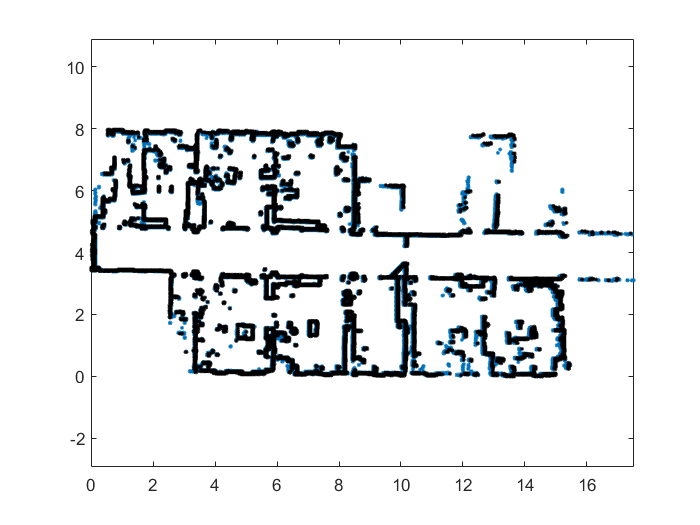

figure;
obtain2d(pointCMap2,'.');hold on;
transMap=opMotion*[pointCMap1';ones(1,length(pointCMap1))];
obtain2d(transMap,'.k');




% obtain2d(zSeleCorM2.Location,'+r');
% transFeaPoint=opMotion*[zSeleCorM1.Location';ones(1,length(zSeleCorM1.Location))];
% obtain2d(transFeaPoint,'xm');
% pcshow(pcMap3d2);hold on;
% pcshow(pctransform(pcMap3d1,affine3d(Motion')));
% imshow(imrotate(map1,74.0));
% imshowpair(map1,map2);
% imshow(imresize(map1,[200,200]));